Question 1

(a) Wilkinson Matrix

format long e
W = Wilkinson(5);
disp(W);

     1     0     0     0     1
    -1     1     0     0     1
    -1    -1     1     0     1
    -1    -1    -1     1     1
    -1    -1    -1    -1     1



(b) Hamiltonian Matrix

H = Hamiltonian(3);
disp(H);

     9.441997267473083e-01    -7.043017284336089e-01     1.521013239005587e+00    -1.392409600065778e+00     5.944630457374454e-01    -1.147380099446467e-01
    -2.120426688224212e+00    -1.018137216399071e+00    -3.843876388671156e-02     5.944630457374454e-01    -5.024147491377636e-01     4.018146265691888e-01
    -6.446789155419369e-01    -1.820818684113852e-01     1.227447989009717e+00    -1.147380099446467e-01     4.018146265691888e-01     1.778345236825198e+00
     4.618574971904773e+00     1.437779497532469e+00     4.737103833615035e-01    -9.441997267473083e-01     2.120426688224212e+00     6.446789155419369e-01
     1.437779497532469e+00     1.118813577768040e-01    -1.112074968581539e+00     7.043017284336089e-01     1.018137216399071e+00     1.820818684113852e-01
     4.737103833615035e-01    -1.112074968581539e+00    -5.524357187095179e-01    -1.521013239005587e+00     3.843876388671156e-02    -1.227447989009717e+00



Question 2

A = rand(8)

A =      2.010398061147072e-01     6.062687099120523e-01     2.360550732931005e-01     1.442116762372380e-01     2.551015772486168e-01     1.598484578615894e-01     3.553533315960447e-01     7.356173228133357e-01
     8.723539423565155e-01     6.774204157255943e-02     8.204315652625026e-01     7.062857318519447e-01     6.982977156162133e-02     6.722389208297781e-01     5.610817305675267e-01     7.635893576702198e-01
     4.187479305624220e-01     7.968471321759872e-01     2.387031555942687e-01     2.460404668680052e-01     3.649199883393652e-01     4.936771045769120e-01     6.112121717470125e-01     2.323635173736407e-01
     9.561001456034209e-01     7.999252020029955e-02     9.136371477665693e-01     6.885147845163880e-01     6.806010393878338e-01     1.657735115732675e-01     4.991020679354971e-01     3.283245972122641e-01
     3.388137342993913e-01     2.394964606331885e-01     4.678684351723762e-01     9.621453551889536e-01     1.759369614941201e-02     8.192411167880945e-01    

max_each_column = max(A)

max_each_column =      9.561001456034209e-01     7.968471321759872e-01     9.618701665520060e-01     9.621453551889536e-01     6.835938887146491e-01     9.897236392330852e-01     9.556941748112914e-01     7.635893576702198e-01


max_each_row = max(A, [], 2)

max_each_row =      7.356173228133357e-01
     8.723539423565155e-01
     7.968471321759872e-01
     9.561001456034209e-01
     9.621453551889536e-01
     9.897236392330852e-01
     6.965656341494535e-01
     9.556941748112914e-01


max_overall = max(A, [], "all")

max_overall =      9.897236392330852e-01


[row_indices, col_indices] = find(A > 0.25);
indices = [row_indices, col_indices]

indices =      2     1
     3     1
     4     1
     5     1
     6     1
     7     1
     1     2
     3     2
     6     2
     2     3


Question 3

n_vals = [3, 5, 7];
for i=1:length(n_vals)
    x = n_vals(i);
    disp(['Magic Square for n = ', num2str(x)]);
    A = magic(x)
    col_sum = sum(A)
    row_sum = sum(A, 2)
    diagonal_sum = trace(A)
    antidiagonal_sum = trace(flipud(A))
end

Magic Square for n = 3


A =      8     1     6
     3     5     7
     4     9     2


col_sum =     15    15    15


row_sum =     15
    15
    15


diagonal_sum =     15


antidiagonal_sum =     15


Magic Square for n = 5


A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


col_sum =     65    65    65    65    65


row_sum =     65
    65
    65
    65
    65


diagonal_sum =     65


antidiagonal_sum =     65


Magic Square for n = 7


A =     30    39    48     1    10    19    28
    38    47     7     9    18    27    29
    46     6     8    17    26    35    37
     5    14    16    25    34    36    45
    13    15    24    33    42    44     4
    21    23    32    41    43     3    12
    22    31    40    49     2    11    20


col_sum =    175   175   175   175   175   175   175


row_sum =    175
   175
   175
   175
   175
   175
   175


diagonal_sum =    175


antidiagonal_sum =    175


Question 4

disp('Question 4')

Question 4


x = 4;
A = magic(x)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


sum(A)

ans =     34    34    34    34


sum(A')'

ans =     34
    34
    34
    34


sum(diag(A))

ans =     34


sum(diag(flipud(A)))

ans =     34


rank(A)

ans =      3


p = randperm(x);
q = randperm(x);
A = A(p, q);
sum(A)

ans =     34    34    34    34


sum(A')'

ans =     34
    34
    34
    34


sum(diag(A))

ans =     34


sum(diag(flipud(A)))

ans =     34


rank(A)

ans =      3


A = magic(4);
null(A)

ans =     -2.236067977499789e-01
    -6.708203932499369e-01
     6.708203932499369e-01
     2.236067977499788e-01


null(A, 'r')

ans =     -1
    -3
     3
     1


rref(A)

ans =      1     0     0     1
     0     1     0     3
     0     0     1    -3
     0     0     0     0


Question 5

A = rand(3);
A^(-1)

ans =      2.234908492678128e+00     1.157668748950134e-01    -9.969463827894837e-01
    -4.002099278908119e+00     2.970309415314781e+00     7.568999968288664e-01
     6.669411974184231e-01    -9.083839075699479e-01     1.600763805984077e+00


1./A

ans =      2.078857724163930e+00     1.570719489777494e+01     3.710828414123385e+00
     1.637019575229782e+00     2.666800424177427e+00     4.922736550733101e+00
     6.838530841844724e+00     5.368699871488372e+00     1.593117076154765e+00


A.^(-1)

ans =      2.078857724163930e+00     1.570719489777494e+01     3.710828414123385e+00
     1.637019575229782e+00     2.666800424177427e+00     4.922736550733101e+00
     6.838530841844724e+00     5.368699871488372e+00     1.593117076154765e+00


1./A

ans =      2.078857724163930e+00     1.570719489777494e+01     3.710828414123385e+00
     1.637019575229782e+00     2.666800424177427e+00     4.922736550733101e+00
     6.838530841844724e+00     5.368699871488372e+00     1.593117076154765e+00


Question 6

p = [1 5 3 10 12]

p =      1     5     3    10    12


syms x;
polynomial = poly2sym(p, x);
disp(polynomial);

$$x^{4}+5\,x^{3}+3\,x^{2}+10\,x+12$$

pdash = (length(p)-1:-1:0).*p

pdash =      4    15     6    10     0


polynomialdash = poly2sym(pdash(1:length(p)-1), x);
disp(polynomialdash);

$$4\,x^{3}+15\,x^{2}+6\,x+10$$

It gives the coefficients of the differentiated polynomial.

Question 7

A1 = eye(16);
A2 = diag(ones(1, 15), 1);
A3 = diag(ones(1, 15), -1);
A = -2.*A1 + A2 + A3;
disp(A);

    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0
     0     0     0     0     0


toeplitz([-2 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0])

ans =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


temp = [1 2 3 4 5 6 7 8];
disp(triu(toeplitz(temp)))

     1     2     3     4     5     6     7     8
     0     1     2     3     4     5     6     7
     0     0     1     2     3     4     5     6
     0     0     0     1     2     3     4     5
     0     0     0     0     1     2     3     4
     0     0     0     0     0     1     2     3
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     0     1



temp = 1./temp;
format rational
disp(toeplitz(temp))

       1              1/2            1/3            1/4            1/5            1/6            1/7            1/8     
       1/2            1              1/2            1/3            1/4            1/5            1/6            1/7     
       1/3            1/2            1              1/2            1/3            1/4            1/5            1/6     
       1/4            1/3            1/2            1              1/2            1/3            1/4            1/5     
       1/5            1/4            1/3            1/2            1              1/2            1/3            1/4     
       1/6            1/5            1/4            1/3            1/2            1              1/2            1/3     
       1/7            1/6            1/5            1/4            1/3            1/2            1              1/2     
       1/8            1/7            1/6            1/5            1/4            1/3            1/2            1       



Question 8

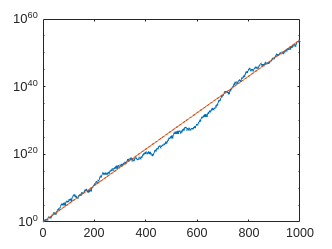

rand('state', 1000)
x = [1, 2];
for n=2:999, x(n+1) = x(n)+sign( rand-0.5)*x(n-1); end
semilogy (1:1000, abs(x))
c =1.13198824;
hold on
semilogy(1:1000, c.^ [1:1000])
hold off

This code tests the assertion $|  x_n | = \mathcal{O}(c^n)$ by plotting both the curves and putting y axis in a logarithmic scale. From the graph we can verify that the assertion is true.

Question 9

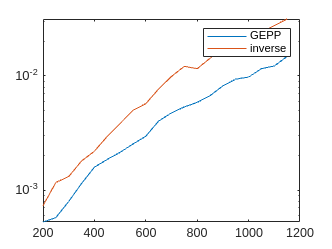

format long e
rand('state', 1000)
time1 = zeros(1, 20);
time2 = zeros(1, 20);
matrix_sizes = zeros(1, 20);
for i = 200:50:1150
    matrix_sizes(i/50 - 3) = i;
    A = rand(i);
    b = rand(i, 1);
    tic
    x1 = A\b;
    time1(i/50 - 3) = toc;
    tic
    x2 = inv(A)*b;
    time2(i/50 - 3) = toc;
end
semilogy(matrix_sizes, time1, 'DisplayName', 'GEPP')
hold on
semilogy(matrix_sizes, time2, 'DisplayName', 'inverse')
hold off
legend('show')

As expected inverse method is taking more time than GEPP.

function W = Wilkinson(n)
    W = -1.*ones(5);
    W = tril(W);
    W = W + 2.*eye(n);
    W(:, end) = 1;
end

function H = Hamiltonian(n)
    H11 = randn(n);
    H22 = -1.*transpose(H11);
    H12 = randn(n);
    H12 = H12 + transpose(H12);
    H21 = randn(n);
    H21 = H21 + transpose(H21);
    H = [H11 H12; H21 H22];
end